
% Get all .wav files in the directory
files = dir(fullfile('Training_Data', '*.wav'));

% Extract numeric values from filenames for correct sorting
fileNames = {files.name};
numValues = zeros(length(fileNames), 1);

for i = 1:length(fileNames)
    numStr = regexp(fileNames{i}, '\d+', 'match'); % Extract numeric part
    numValues(i) = str2double(numStr{1}); % Convert to number
end

% Sort files numerically
[~, sortedIdx] = sort(numValues);
files = files(sortedIdx); % Reorder file structure

% Number of files
numFiles = length(files);

% Define subplot grid size (adjust dynamically)
rows = ceil(sqrt(numFiles));  % Auto-adjust rows
cols = ceil(numFiles / rows); % Auto-adjust columns
numPlots = min(numFiles, rows * cols); % Ensure we don't exceed available subplots

figure; % Create a new figure


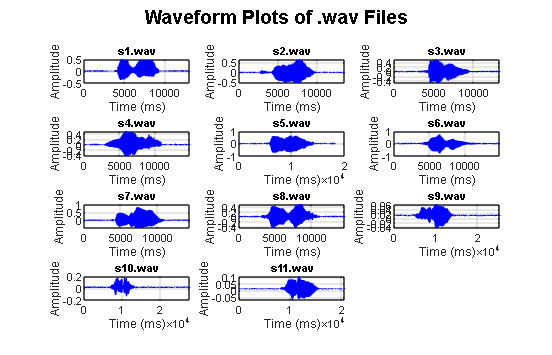



for i = 1:numPlots
    % Construct full filename
    filename = fullfile(files(i).folder, files(i).name);
    
    % Read the audio file
    [signal, fs] = audioread(filename);

    %normalize signal
    %signal = normalize(signal, 'range', [-1,1]); 
    
    % Convert stereo to mono (if necessary)
    if size(signal, 2) == 2
        signal = mean(signal, 2); % Take the average of both channels
    end
    
    % Select subplot position
    subplot(rows, cols, i);
    plot(signal, 'b'); % Force a consistent color (blue)
    
    % Formatting each subplot
    title(files(i).name, 'Interpreter', 'none', 'FontSize', 8);
    xlabel('Time (ms)');
    ylabel('Amplitude');
    grid on;
end

% Adjust figure layout
sgtitle('Waveform Plots of .wav Files', 'FontSize', 14, 'FontWeight', 'bold'); % Overall title
set(gcf, 'Position', [100, 100, 1400, 900]); % Resize figure for better layout

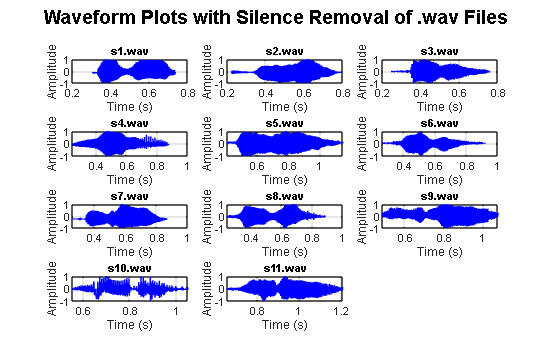

%voice audio detection. removal of signal that is in silence or below 35(?)
energyThreshold = 0.0005; % Adjust this threshold for silence detection


for i = 1:numPlots
    % Construct full filename
    filename = fullfile(files(i).folder, files(i).name);
    
    % Read the audio file
    [signal, fs] = audioread(filename);

    % Normalize the signal
    %signal = normalize(signal, 'range', [-1, 1]);
    
    % Convert stereo to mono (if necessary)
    if size(signal, 2) == 2
        signal = mean(signal, 2); % Take the average of both channels
    end
    
    % Remove silence at the beginning and end using energy threshold
    % Calculate the energy of the signal (squared values)
    energy = signal.^2;
    
    % Define a threshold to consider the signal as non-silent
    nonSilentIdx = energy > energyThreshold;
    
    % Find the indices of the non-silent portion
    speechStart = find(nonSilentIdx, 1, 'first');
    speechEnd = find(nonSilentIdx, 1, 'last');
    
    % Trim the signal to include only the non-silent portion
    trimmedSignal = signal(speechStart:speechEnd);

    %normalize trimmed signal
    signal = normalize(trimmedSignal, 'range', [-1,1]); 

    % Select subplot position
    subplot(rows, cols, i);
    plot((speechStart:speechEnd)/fs, signal, 'b'); % Plot the trimmed signal
    
    % Formatting each subplot
    title(files(i).name, 'Interpreter', 'none', 'FontSize', 8);
    xlabel('Time (s)');
    ylabel('Amplitude');
    grid on;
end

% Adjust figure layout
sgtitle('Waveform Plots with Silence Removal of .wav Files', 'FontSize', 14, 'FontWeight', 'bold'); % Overall title

set(gcf, 'Position', [100, 100, 1400, 900]);


window = 256

window = 256

overlap = window - (window/3);
nfft = 256

nfft = 256

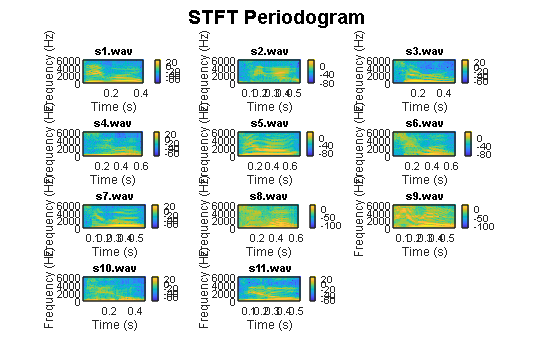



% Define subplot grid size (adjust dynamically)
rows = ceil(sqrt(numFiles));  % Auto-adjust rows
cols = ceil(numFiles / rows); % Auto-adjust columns
numPlots = min(numFiles, rows * cols); % Ensure we don't exceed available subplots

figure; % Create a new figure


for i = 1:numPlots
    % Construct full filename
    filename = fullfile(files(i).folder, files(i).name);
    
    % Read the audio file
    [signal, fs] = audioread(filename);

    % Normalize the signal
    %signal = normalize(signal, 'range', [-1, 1]);
    
    % Convert stereo to mono (if necessary)
    if size(signal, 2) == 2
        signal = mean(signal, 2); % Take the average of both channels
    end
    
    % Remove silence at the beginning and end using energy threshold
    % Calculate the energy of the signal (squared values)
    energy = signal.^2;
    
    % Define a threshold to consider the signal as non-silent
    nonSilentIdx = energy > energyThreshold;
    
    % Find the indices of the non-silent portion
    speechStart = find(nonSilentIdx, 1, 'first');
    speechEnd = find(nonSilentIdx, 1, 'last');
    
    % Trim the signal to include only the non-silent portion
    trimmedSignal = signal(speechStart:speechEnd);

    %normalize trimmed signal
    signal = normalize(trimmedSignal, 'range', [-1,1]); 

    %do stft 
    [s,f,t] = stft(signal, fs, 'Window', hamming(window), 'OverlapLength', round(overlap), 'FFTLength', nfft);
    
    % Select only positive frequencies
    positiveFreqIdx = f >= 0; 
    

    subplot(rows, cols, i);
    %imagesc(t, f(positiveFreqIdx), real(s(positiveFreqIdx, :)));
    imagesc(t, f(positiveFreqIdx), 20*log10(abs(s(positiveFreqIdx, :)) + eps));
    %eps revents a log(0)

    axis xy;
    xlabel('Time (s)');
    ylabel('Frequency (Hz)');
    title(files(i).name, 'Interpreter', 'none', 'FontSize', 8);

    colorbar;


end

% Adjust figure layout
sgtitle('STFT Periodogram' , 'FontSize', 14, 'FontWeight', 'bold'); % Overall title
set(gcf, 'Position', [100, 100, 1400, 900]); % Resize figure for better layout

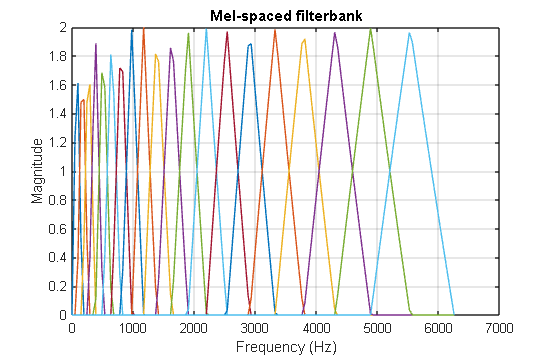

fs = 12500;       % Sampling frequency (Hz)
nfft = 256;       % FFT size
k = 20;  % Number of Mel filters

% Generate Mel filter bank (requires Voicebox Toolbox)
%melfilterbank = melbankm(k, nfft, fs, 0, 0.5, 'm'); 
melfilterbank = melfb(k,nfft,fs);
%disp(melfb);
% Frequency axiss in Hz
freqs = linspace(0, fs/2, nfft/2+1); 

% Plot Mel filter bank response
figure;
plot(freqs, melfilterbank');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Mel-spaced filterbank');
grid on;


set(gcf, 'Position', [100, 100, 1400, 900]); % Resize figure for better layout

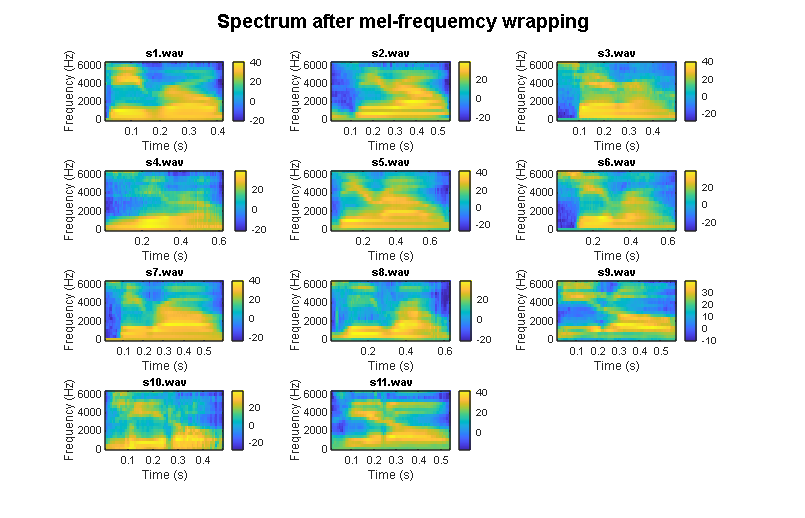

% Parameters
window = 256;
overlap = window - (window/3);
nfft = 256;

% Define subplot grid size (adjust dynamically)
rows = ceil(sqrt(numFiles));  % Auto-adjust rows
cols = ceil(numFiles / rows); % Auto-adjust columns
numPlots = min(numFiles, rows * cols); % Ensure we don't exceed available subplots

figure; % Create a new figure

for i = 1:numPlots
    % Construct full filename
    filename = fullfile(files(i).folder, files(i).name);
    
    % Read the audio file
    [signal, fs] = audioread(filename);

    % Normalize the signal
    %signal = normalize(signal, 'range', [-1, 1]);
    
    % Convert stereo to mono (if necessary)
    if size(signal, 2) == 2
        signal = mean(signal, 2); % Take the average of both channels
    end
    
    % Remove silence at the beginning and end using energy threshold
    % Calculate the energy of the signal (squared values)
    energy = signal.^2;
    
    % Define a threshold to consider the signal as non-silent
    nonSilentIdx = energy > energyThreshold;
    
    % Find the indices of the non-silent portion
    speechStart = find(nonSilentIdx, 1, 'first');
    speechEnd = find(nonSilentIdx, 1, 'last');
    
    % Trim the signal to include only the non-silent portion
    trimmedSignal = signal(speechStart:speechEnd);

    %normalize trimmed signal
    signal = normalize(trimmedSignal, 'range', [-1,1]); 

    % Perform STFT
    [s, f, t] = stft(signal, fs, 'Window', hamming(window), 'OverlapLength', round(overlap), 'FFTLength', nfft);
    
     % Select only positive frequencies
    positiveFreqIdx = f >= 0; 
    f_pos = f(positiveFreqIdx);
    s_pos = s(positiveFreqIdx, :);

    %imagesc(t, f(positiveFreqIdx), real(s(positiveFreqIdx, :)));
    %imagesc(t, f(positiveFreqIdx), 20*log10(abs(s(positiveFreqIdx, :)) + eps));
    %eps revents a log(0)


    % Apply mel filter bank if necessary
    melfb_response = melfilterbank * abs(s_pos);
    
    
    % Create the subplot
    subplot(rows, cols, i);
    
    % Plot only positive frequencies
    imagesc(t, f_pos, 20*log10(abs(melfb_response) + eps)); % eps avoids log(0)
    
    % Adjust plot axes and labels
    axis xy;
    xlabel('Time (s)');
    ylabel('Frequency (Hz)');
    title(files(i).name, 'Interpreter', 'none', 'FontSize', 8);

    colorbar;
end

% Adjust figure layout
sgtitle('Spectrum after mel-frequemcy wrapping', 'FontSize', 14, 'FontWeight', 'bold'); % Overall title
set(gcf, 'Position', [100, 100, 1400, 900]); % Resize figure for better layout

% Parameters
window = 256;
overlap = window - (window/3);
nfft = 256;

% Define subplot grid size (adjust dynamically)
rows = ceil(sqrt(numFiles));  % Auto-adjust rows
cols = ceil(numFiles / rows); % Auto-adjust columns
numPlots = min(numFiles, rows * cols); % Ensure we don't exceed available subplots

figure; % Create a new figure

for i = 1:numPlots
    % Construct full filename
    filename = fullfile(files(i).folder, files(i).name);
    
    % Read the audio file
    [signal, fs] = audioread(filename);

    % Normalize the signal
    %signal = normalize(signal, 'range', [-1, 1]);
    
    % Convert stereo to mono (if necessary)
    if size(signal, 2) == 2
        signal = mean(signal, 2); % Take the average of both channels
    end
    
    % Remove silence at the beginning and end using energy threshold
    % Calculate the energy of the signal (squared values)
    energy = signal.^2;
    
    % Define a threshold to consider the signal as non-silent
    nonSilentIdx = energy > energyThreshold;
    
    % Find the indices of the non-silent portion
    speechStart = find(nonSilentIdx, 1, 'first');
    speechEnd = find(nonSilentIdx, 1, 'last');
    
    % Trim the signal to include only the non-silent portion
    trimmedSignal = signal(speechStart:speechEnd);

    %normalize trimmed signal
    signal = normalize(trimmedSignal, 'range', [-1,1]); 
    
    % Perform STFT
    [s, f, t] = stft(signal, fs, 'Window', hamming(window), 'OverlapLength', round(overlap), 'FFTLength', nfft);
    
     % Select only positive frequencies
    positiveFreqIdx = f >= 0; 
    f_pos = f(positiveFreqIdx);
    s_pos = s(positiveFreqIdx, :);

    % Apply mel filter bank
    melfb_response = melfilterbank * abs(s_pos);
    logMelSpectrogram = log(melfb_response);
    cepstrum = dct(logMelSpectrogram);
    numCoefficients = 20;  
    cepstrum = cepstrum(2:numCoefficients, :);
    disp(filename);
    disp(cepstrum);

    % Create the subplot
    subplot(rows, cols, i);
    
    % Plot only positive frequencies
    %imagesc(t, cepstrum(1,:), 20*log(abs(cepstrum))); % eps avoids log(0)
    imagesc(t, 2:numCoefficients, cepstrum)
    % Adjust plot axes and labels
    axis xy;
    xlabel('Time (s)');
    ylabel('Coefficients');
    title(files(i).name, 'Interpreter', 'none', 'FontSize', 8);
    
    colorbar;
end

\\coe-itss-bfs.engr.ucdavis.edu\StudentDocs$\katdjksm\Desktop\FinalProject201_Voicehackers\Training_Data\s1.wav


   -3.9552   -2.2057    0.9819    1.8596    1.5724    1.8867    1.6514    1.6807    1.3218    1.1797    1.1804    0.9324    1.0292    1.2184    1.3293    1.3326    1.8534    2.5787    2.7736    4.5805    4.9397    5.5535    5.9321    6.0730    6.3672    6.3035    6.5342    6.9060    6.8974    6.2586    6.1869    6.2108    6.4875    6.6390    6.8020    6.7903    6.8183    6.3134    6.6839    6.3441    6.2956    6.1584    5.3504    5.9333    6.0807    5.6050    6.0255    6.3418    6.1660    5.8373    6.4179    5.7742    6.0432    6.7387    6.0888    6.6688    6.9994    7.6897    8.1357    7.6747    6.7985
    1.0541    3.0201    4.7106    3.0764    2.5880    2.4199    2.5571    2.4636    2.7317    2.7462    2.8750    3.0473    3.0432    2.8106    2.8297    2.5229    2.1247    1.3768    1.5314    0.4855    0.9869    1.0078    1.0654    1.0483    0.3731    0.2182    0.0812   -0.0284   -0.3718   -0.1587   -0.2662   -0.5033   -0.9465   -1.2051   -1.6397   -1.7487   -2.0628   -1.6320   -1.910

\\coe-itss-bfs.engr.ucdavis.edu\StudentDocs$\katdjksm\Desktop\FinalProject201_Voicehackers\Training_Data\s2.wav


    5.8575    5.3857    4.8285    4.2728    3.7174    3.2097    2.7547    1.5713    1.6711    1.5026    1.1019    0.5366    0.0430   -0.6188   -0.6399   -0.4694    0.8430    1.3757    2.1341    3.0562    3.0305    3.1312    3.2707    3.0054    2.7894    2.9817    2.7357    2.4555    2.7258    2.9265    2.6626    2.9690    3.2544    3.7049    3.4628    4.8051    4.7585    4.6949    4.1766    4.3157    5.7658    4.5094    3.8095    4.1359    4.3776    4.2170    3.9821    4.0681    3.6921    3.6965    4.1515    3.9817    3.5834    3.7079    3.5007    3.9186    3.2628    3.7080    3.5114    3.6701    3.9678    4.0178    3.6634    4.4257    4.5239    4.5564    4.3674    5.0818    5.3483    5.3800    5.2394    5.3742    5.5565    6.1846    5.7454    6.4568    7.0668    7.6231    6.8308    5.9441    6.1446
    4.0704    4.2120    4.1685    4.5632    4.2620    4.3973    4.0996    4.6076    4.4935    4.6490    5.0705    4.4483    3.8549    3.4071    3.0511    3.4068    3.0327    3.1618    3.057

\\coe-itss-bfs.engr.ucdavis.edu\StudentDocs$\katdjksm\Desktop\FinalProject201_Voicehackers\Training_Data\s3.wav


   -4.9515   -5.0185   -4.9702   -5.0078   -5.5589   -5.1726   -4.9718   -4.4960   -4.6176   -5.2515   -5.5837   -4.3853   -1.6573    2.0440    3.9709    3.8048    3.4442    3.4684    2.9790    3.1815    3.2457    3.0857    3.1664    3.2127    3.5696    3.5127    3.7109    4.0433    4.1996    4.4346    4.6648    5.5512    5.9016    6.1634    6.4969    6.8694    6.4785    7.1838    7.1892    7.1342    7.3573    6.9215    7.0805    6.9213    6.4225    6.1188    6.4452    5.8209    5.5420    5.7460    5.6946    5.5409    5.7112    5.5585    5.3375    5.6074    5.4580    5.7380    6.0049    5.9650    6.2436    6.2399    6.3080    6.6425    6.4657    6.3542    6.3321    6.1664    6.3387    6.2737    6.2629    5.0761
    1.3866    0.3609    0.7165    1.4172    1.1760    1.0980    1.7416    1.5831    1.2469    1.1235    0.9815    1.5146    3.1659    3.2257    1.0695    0.2027    0.5678    0.1469    0.3668   -0.1235   -0.1356   -0.1355   -0.0501   -0.4483   -0.3531   -0.3085   -0.5300   -1.026

\\coe-itss-bfs.engr.ucdavis.edu\StudentDocs$\katdjksm\Desktop\FinalProject201_Voicehackers\Training_Data\s4.wav


    1.1868    1.5917    1.4337    1.8925    2.4184    2.1381    1.1722    1.2897    1.5758    1.9199    1.7972    2.6449    2.3396    2.3892    2.2129    2.1177    2.0505    2.2995    2.3075    2.2456    2.3001    2.0122    2.1342    2.4751    2.7280    3.5553    3.9078    4.1304    4.3576    4.1846    4.2742    4.2574    4.5490    4.4904    4.4230    4.2780    3.8327    4.0205    4.7221    4.1417    4.7154    4.7477    4.6469    4.8801    4.8989    5.6194    5.7983    6.1054    7.2380    7.1884    6.3380    6.3445    7.0030    7.2281    7.2857    7.1956    6.6887    6.5837    6.5820    6.8461    6.6934    6.6152    6.3341    5.8176    5.6009    5.2764    5.3420    5.2416    5.1263    5.5388    5.3270    4.6078    4.6248    4.2834    4.4191    4.5982    4.8460    5.1733    5.2199    4.7557    6.1563    6.1399    6.5978    6.1050    6.7785    5.2189    6.6285    7.4286    7.9616    7.5827    7.4197
    5.0996    5.8247    6.2582    6.0892    5.9378    6.0538    5.5376    5.3785    5.826

\\coe-itss-bfs.engr.ucdavis.edu\StudentDocs$\katdjksm\Desktop\FinalProject201_Voicehackers\Training_Data\s5.wav


    1.7957    1.7209    1.4471    1.5168    0.9499    1.0055    1.2280    1.5205    2.1519    2.3371    2.3262    2.5686    2.8962    2.7521    2.5111    2.3861    2.2602    2.1015    1.9041    1.8616    1.7740    1.9281    2.0396    2.0545    2.1941    2.4922    2.6701    3.1307    3.2178    3.2765    3.8423    4.0303    4.2377    4.5876    4.7895    5.3941    5.3963    5.6451    6.1425    5.7822    5.9134    6.0027    5.4426    5.8204    5.8155    5.3712    4.9336    4.5483    3.8533    3.6500    3.2681    3.3503    3.0737    3.0762    2.9524    3.0409    2.9735    3.0212    2.9250    2.8405    2.7578    2.7222    2.7011    2.9232    2.9312    3.0789    3.1052    3.2203    3.3672    3.3190    3.3567    3.5503    3.4470    3.7556    3.8994    4.0329    4.2492    4.2799    4.5827    5.0675    4.9923    5.2438    5.3937    5.1691    5.4204    5.7961    5.3788    5.8700    5.6495    5.7109    5.6478    5.6687    6.9620    6.1047    7.5116    7.0138    7.2093    7.5405    7.6338    7.4361

\\coe-itss-bfs.engr.ucdavis.edu\StudentDocs$\katdjksm\Desktop\FinalProject201_Voicehackers\Training_Data\s6.wav


   -6.1737   -5.9959   -6.3540   -6.3159   -6.5823   -6.5142   -5.7409   -6.1477   -6.5090   -6.2957   -6.5795   -7.2095   -7.1909   -6.9644   -6.3127   -4.7335   -2.2622   -0.8989   -0.0955    0.4534    1.1714    1.2339    1.6265    1.4307    1.2985    1.3023    1.4542    1.3998    1.5281    1.9050    2.1244    2.3499    2.2679    2.6239    3.2129    3.6651    3.8437    4.5246    4.3876    5.0664    5.6675    5.5679    5.7805    5.4478    5.8123    5.9503    5.3485    6.1774    6.2962    6.2397    6.4492    6.6150    6.4092    6.5353    6.1415    5.0424    5.6902    5.4633    4.7883    5.0640    4.9379    4.6450    4.2921    4.5210    4.7634    4.4583    4.1440    4.4062    4.3645    3.8523    3.5730    3.3685    3.8153    3.9705    4.2659    4.1942    4.7742    5.0174    5.1918    5.0165    4.7687    5.6534    5.7558    5.7906    5.3212    6.0339    5.5780    5.9165    5.7011    5.9854    5.6769    5.7535    4.8343    5.0418
    3.8198    3.9724    2.7995    2.9157    3.2478    3.035

\\coe-itss-bfs.engr.ucdavis.edu\StudentDocs$\katdjksm\Desktop\FinalProject201_Voicehackers\Training_Data\s7.wav


   -3.0116   -2.3472   -2.4181   -2.8849   -2.8595   -3.0643   -3.0627   -2.8554   -2.9637   -2.0325   -1.7357    0.8727    3.1404    3.1406    2.8434    2.4184    1.9925    2.0095    2.0966    2.2958    2.4941    2.4163    2.6334    3.0400    3.2803    3.9127    4.3109    4.7548    5.4414    5.5245    5.9950    6.0012    7.3257    5.9643    6.1832    7.3023    7.3904    7.3042    7.6405    7.3116    7.4411    6.2358    6.5615    5.1658    5.7286    5.2970    5.1195    4.8545    4.8314    4.5730    4.8085    4.4809    4.1141    4.7163    4.4537    4.6057    4.7142    4.6004    4.6037    4.2114    4.5817    4.2832    4.4459    4.5398    4.6363    4.6751    4.6017    4.9961    4.8354    4.9923    5.1909    5.2379    5.3627    5.3532    5.7608    5.8309    6.0867    6.1644    6.3214    6.9387    6.4851    6.6186    6.4163    6.3108    6.4986    6.4502    6.0575
    4.1051    3.1896    3.0984    4.1500    4.6794    3.6340    3.3620    2.7530    2.9204    3.6799    4.3298    4.7991    2.446

\\coe-itss-bfs.engr.ucdavis.edu\StudentDocs$\katdjksm\Desktop\FinalProject201_Voicehackers\Training_Data\s8.wav


   -0.9619   -1.0591   -1.2794   -0.2134    0.9422    0.4884   -0.3223   -0.1828   -0.0443    0.3783    1.1530    2.0568    1.8263    2.3433    2.9454    3.0217    3.0558    2.9455    3.0928    2.7520    2.8074    2.3784    2.3372    2.6600    2.4447    2.4850    2.3290    2.3894    2.5820    2.4939    2.7024    2.8649    3.0482    3.5353    4.1036    4.8523    5.1507    4.6471    5.0829    5.1085    4.5686    4.4287    4.4897    4.5459    5.0531    4.6267    6.0878    6.0519    6.2814    6.5429    5.7344    6.3026    6.1747    5.9454    5.6206    5.4375    5.1667    5.0841    4.9845    4.6985    4.5994    4.6776    4.5851    4.5899    4.3760    4.3239    4.3676    3.9339    4.2124    4.2563    4.5145    4.6334    4.8052    4.6261    4.8846    5.6444    5.8720    6.4484    5.8399    5.5427    6.6860    6.8409    6.6712    5.3625    7.2620    7.2927    7.1565    7.4201    7.2036    6.0739    5.7280    5.1859
    5.7652    5.7655    5.7790    3.7910    1.3485    2.3581    3.9526    3.862

\\coe-itss-bfs.engr.ucdavis.edu\StudentDocs$\katdjksm\Desktop\FinalProject201_Voicehackers\Training_Data\s9.wav


   -0.2432   -0.1291    0.0823   -0.0510   -1.0128   -1.1143   -1.2585   -1.0523   -1.1232   -1.0687   -1.1057   -1.2087   -1.4897   -1.8916   -1.9447   -1.8013   -1.7689   -1.9572   -1.7842   -1.4682   -1.2806   -1.2773   -1.1593   -0.7589   -0.6915   -0.1983    0.3747    0.5656    1.0041    1.1756    1.3098    1.8080    1.8353    1.8324    2.4587    3.0802    3.4178    4.1001    4.0062    3.1933    2.8247    2.7324    2.2366    1.8604    1.8767    1.7013    1.4924    1.4130    1.4554    1.5569    1.5929    1.8089    1.8849    2.0603    2.3982    2.4798    2.3691    2.6701    2.7943    2.5119    2.9693    3.4948    3.7932    3.5556    4.0681    4.1515    3.9324    4.2314    3.9456    3.7479    3.8993    4.3086    4.3097    4.3204    4.6181    4.7643    5.3110    5.4884    5.5042    5.5091    4.9758    4.8153    5.1720    5.8683
    4.5657    4.8212    4.1811    3.9344    4.2223    4.2059    4.0740    3.9040    4.3568    3.9135    3.5702    3.5320    3.6497    3.7296    3.7576    3.554

\\coe-itss-bfs.engr.ucdavis.edu\StudentDocs$\katdjksm\Desktop\FinalProject201_Voicehackers\Training_Data\s10.wav


    5.8934    4.4931    3.3574    2.2725    1.3002    0.8044    1.1990    0.5695    0.1058    0.1373    0.0553    0.3348    1.8885    1.7964    3.0409    3.5184    3.7328    2.9702    2.0670    2.0350    2.0002    2.2125    2.3843    2.2691    2.2170    2.1530    2.2460    2.2395    2.4677    2.8848    3.2777    3.3923    4.1646    4.6528    4.6521    4.2026    2.8212    0.9133    1.1221    3.0423    5.0821    6.6056    7.5821    8.1701    6.5546    7.5371    6.5205    7.0828    7.3432    7.2287    7.5239    6.3073    5.3575    6.6075    6.8006    6.3450    7.2420    6.5849    6.5083    6.2507    6.8754    6.9497    6.8144    6.1590    7.0468    6.2426    5.3199    7.0087    7.7011    6.6318
    2.2669    2.2106    2.2907    3.0734    3.2920    4.5025    3.9983    3.4385    3.3143    3.8498    3.5203    3.3817    3.6366    2.3440    2.2279    2.0562    1.6716    1.4750    1.7419    1.9306    1.7058    1.4735    1.6837    1.7215    1.9844    2.0756    1.8285    2.0116    1.6356    1.305

\\coe-itss-bfs.engr.ucdavis.edu\StudentDocs$\katdjksm\Desktop\FinalProject201_Voicehackers\Training_Data\s11.wav


    5.5581    4.3511    3.6858    2.6795    1.7149    1.1675    0.5700    0.4712    1.3609    2.4689    2.7637    2.5770    2.4523    2.3533    1.8529    1.3022    0.7832    0.7653    0.7149    0.8034    1.1630    1.6871    1.5019    1.9046    1.7444    1.8943    2.2034    2.5603    1.4313    1.5826    2.8855    2.6786    2.8310    1.9780    1.8800    2.7351    3.1453    3.6091    3.5850    3.3387    3.5299    3.8387    3.6749    3.4413    3.3874    3.5181    3.2906    3.4079    3.4382    3.4290    3.0982    3.3687    3.2561    3.1675    3.4665    3.3002    3.2911    3.7816    3.5536    3.4641    3.5616    4.0523    3.8760    3.7978    3.8436    3.8363    3.6338    3.9976    3.9154    4.2114    4.4568    5.2266    5.4959    4.9830    5.6603    5.8501    6.4345    6.3119    6.0444
    1.5270    2.2701    2.5585    3.2653    3.7212    4.5506    4.4573    4.8678    3.9789    2.9194    2.2895    1.6294    1.2913    0.5889    0.5603    1.0208    1.0561    1.0401    0.9871    1.0969    0.721

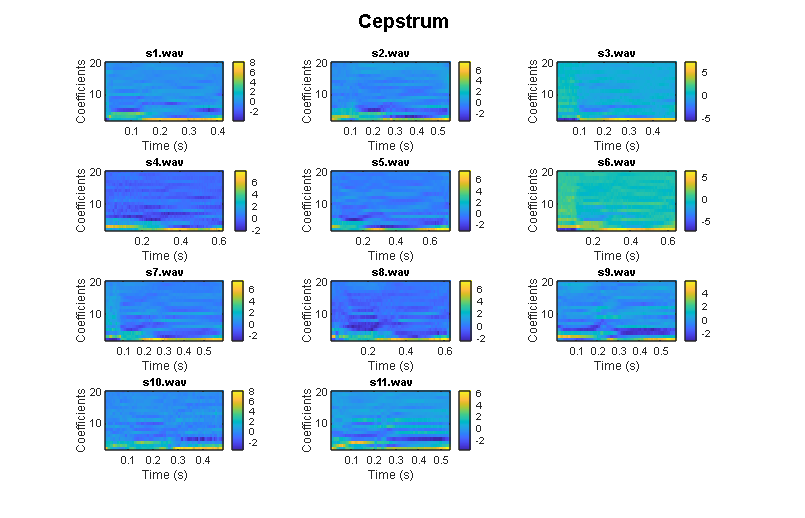


% Adjust figure layout
sgtitle('Cepstrum', 'FontSize', 14, 'FontWeight', 'bold'); % Overall title
set(gcf, 'Position', [100, 100, 1400, 900]); % Resize figure for better layout

%disp(cepstrum)

